# Projeto de avanço de fase utilizando Lugar das raízes

## Boas práticas

clear all;          % limpa as variáveis
clc;                % limpa a tela
close all;          % fecha as figuras abertas


## Definindo o processo a ser controlado


$$G_p(s) = \frac{1}{s+1}
$$


Traduzindo para Matlab

Gp =tf(1,[1 1])

Gp =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



## Desempenho desejado

Deseja-se erro estacionário nulo ao degrau e tempo de acomodação $T_s =2s$ para um polo em malha fechada de $P_{1,2} = -2 \pm j$.

## Inserindo um controlador integral para retirar o erro estacionário

Gc = tf(1,[1 0]);
Gma = Gc*Gp;
Gmf =  feedback(Gma,1);
rlocus(Gma);grid;

if ishold == 0 
    
    hold;
end

Current plot held


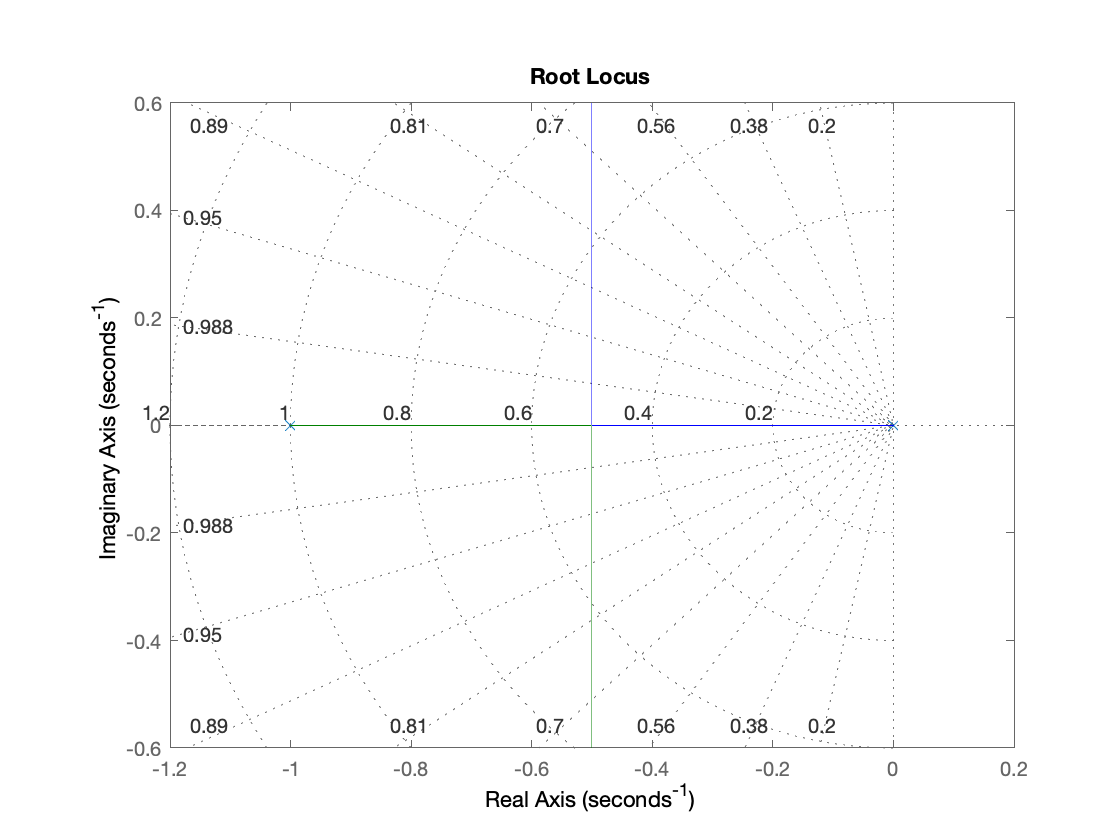


plot(-2,1,'ro','Markersize',10)
yline(1,'r-.','LineWidth',2);xline(-2,'r-.','LineWidth',2);

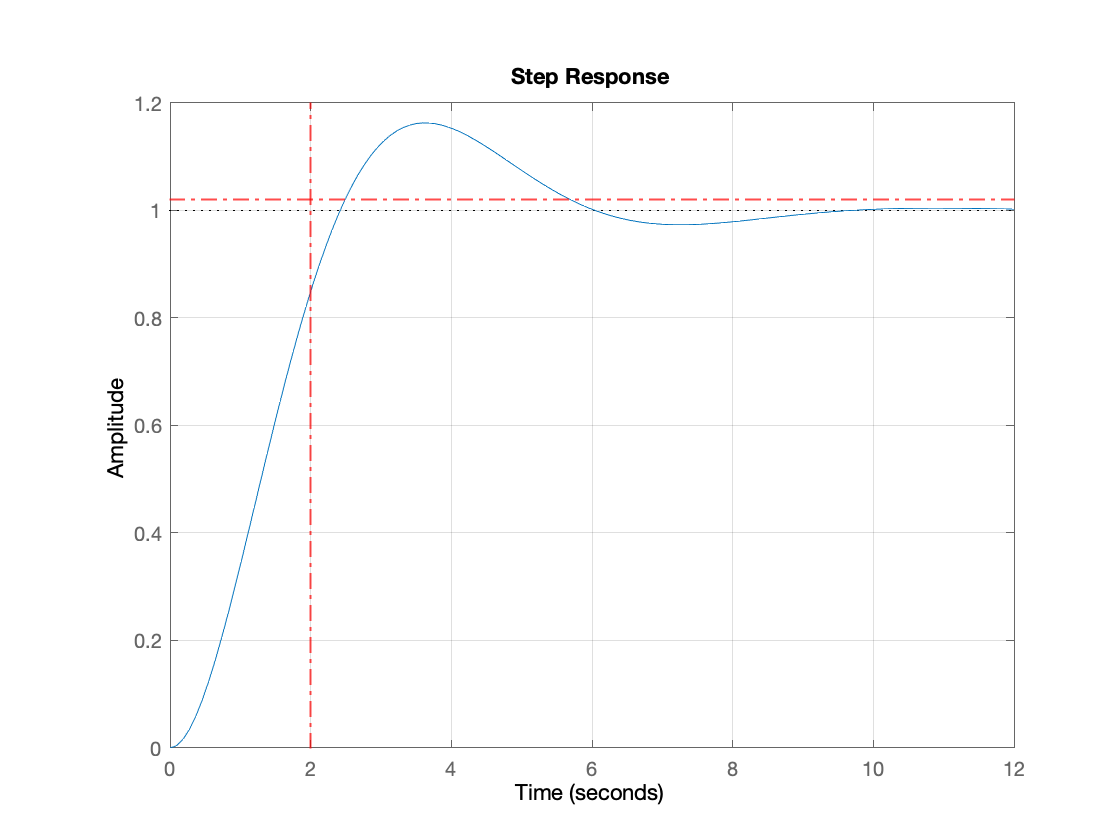

figure()
step(Gmf);
grid;yline(1.02,'r-.','LineWidth',1);xline(2,'r-.','LineWidth',1);

**O integrador ganrante erro estcionário nulo ao degrau, no entento não atende ao desempenho do tempo de acomodação.**

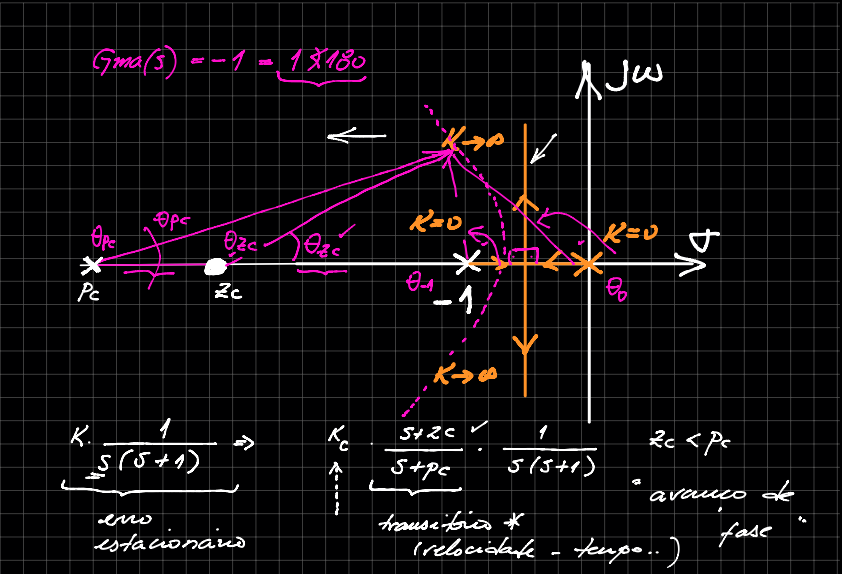

## Projetando um controlador avanço de fase


$$G_c(s) = K_c \frac{s+z_c}{s+p_c} \rightarrow \vert z_c\vert <\vert p_c \vert$$
 

**Esboço do lugar das raízes**

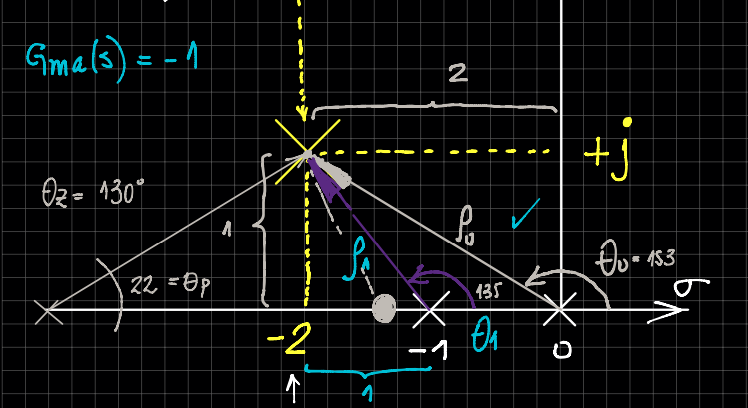

## Controlador final

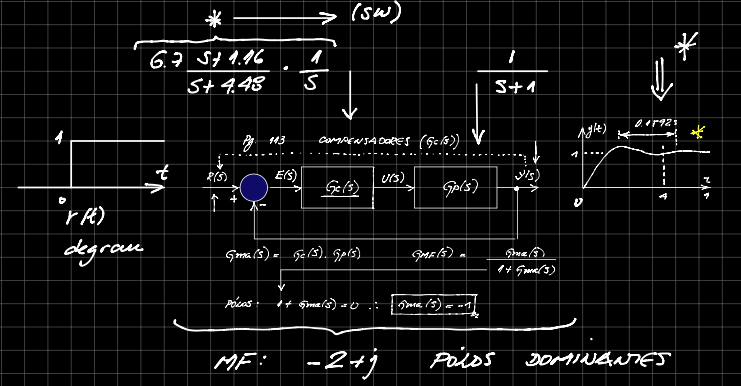

## Traduzindo para o Matlab

Gc = tf(6.7*[1 1.16],[1 4.48 0])

Gc =
 
  6.7 s + 7.772
  -------------
  s^2 + 4.48 s
 
Continuous-time transfer function.



Gma = Gc*Gp

Gma =
 
       6.7 s + 7.772
  -----------------------
  s^3 + 5.48 s^2 + 4.48 s
 
Continuous-time transfer function.



Gmf = feedback(Gma,1)

Gmf =
 
           6.7 s + 7.772
  --------------------------------
  s^3 + 5.48 s^2 + 11.18 s + 7.772
 
Continuous-time transfer function.




rlocus(Gma);grid;

if ishold == 0 
    
    hold;
end

Current plot held


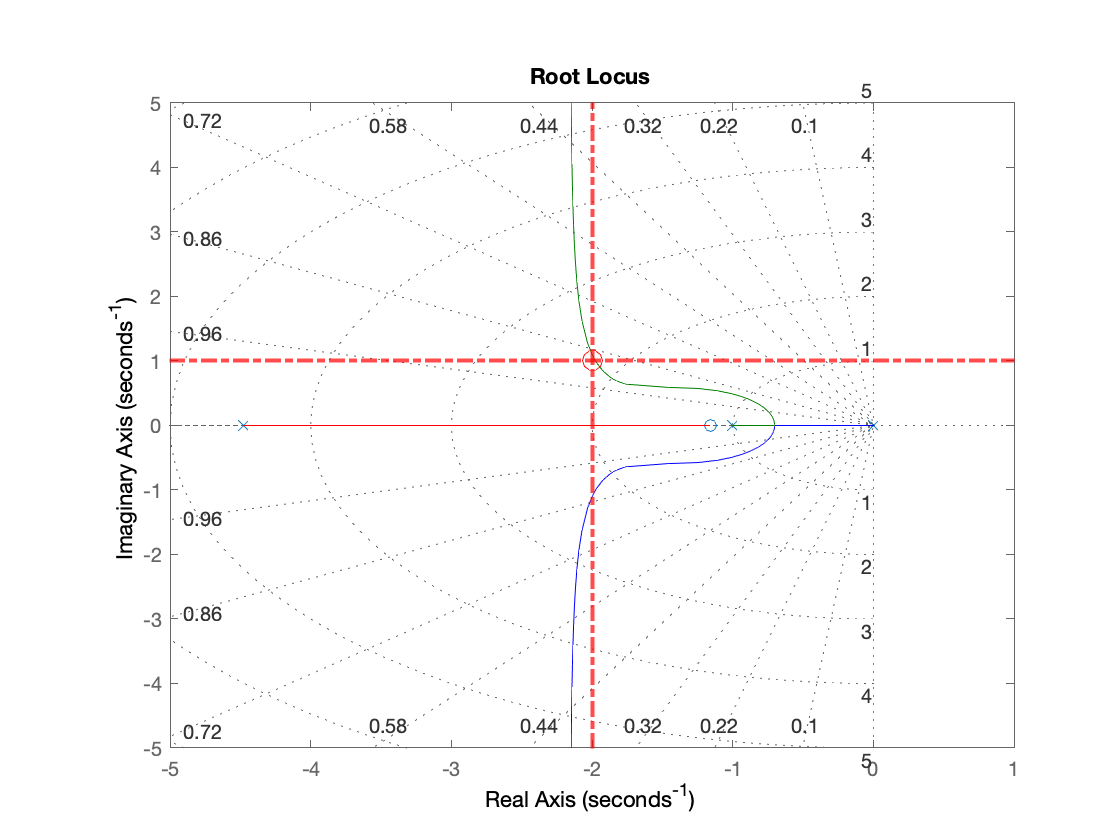


plot(-2,1,'ro','Markersize',10)
yline(1,'r-.','LineWidth',2);xline(-2,'r-.','LineWidth',2);

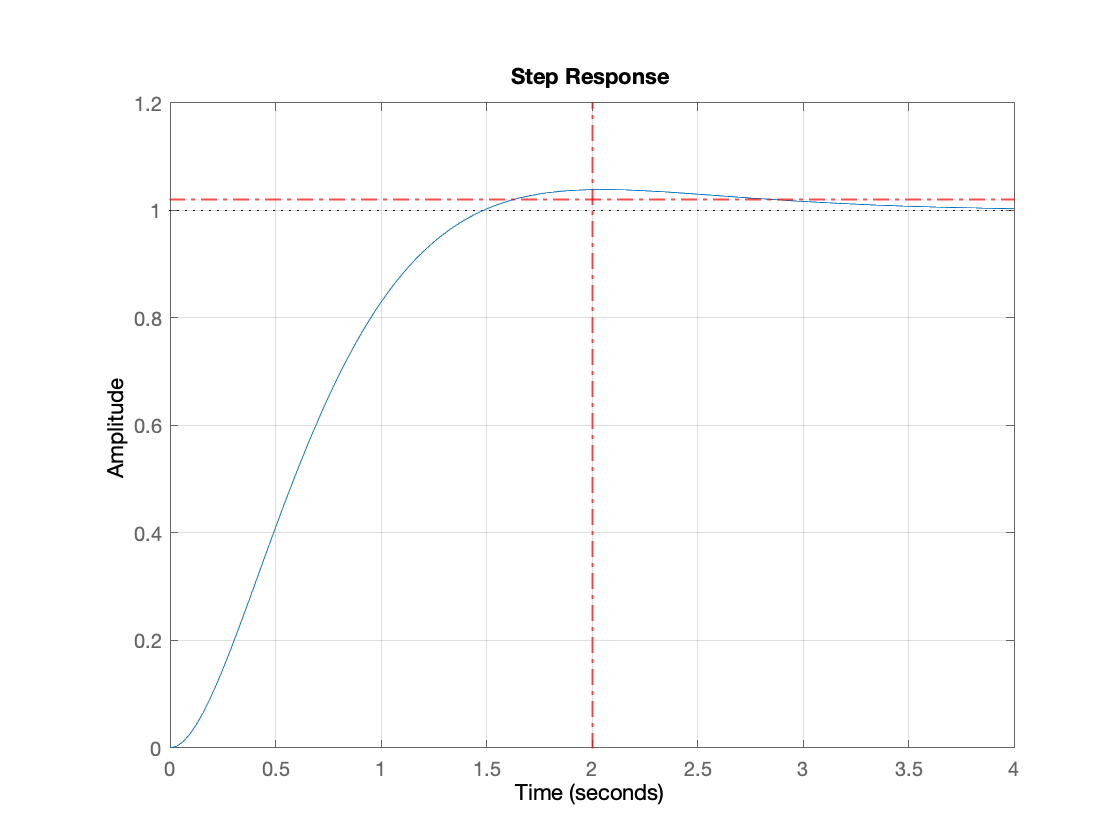

figure()
step(Gmf);
grid;yline(1.02,'r-.','LineWidth',1);xline(2,'r-.','LineWidth',1);

## Polos de malha fechada

aux = cell2mat(Gmf.Denominator)

aux =     1.0000    5.4800   11.1800    7.7720


polos = roots(aux)

polos =   -2.0042 + 1.1244i
  -2.0042 - 1.1244i
  -1.4717 + 0.0000i
